devFrameworkMatlabPostOptislang

## `Project 구조 `

`System>Node`

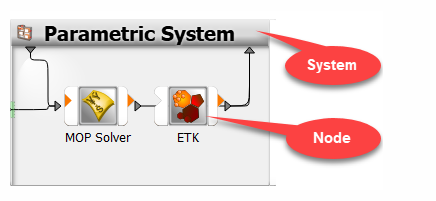

`oslpp `

## OMDB file 구조

| Parameter Manager |

| Design Container |

| Metamodels |

| Approximated designs |

| Validated designs |

| Deactivated designs |

| Reference design |

| Nominal design |

| Algorithm info |

| Postprocessing meta data |

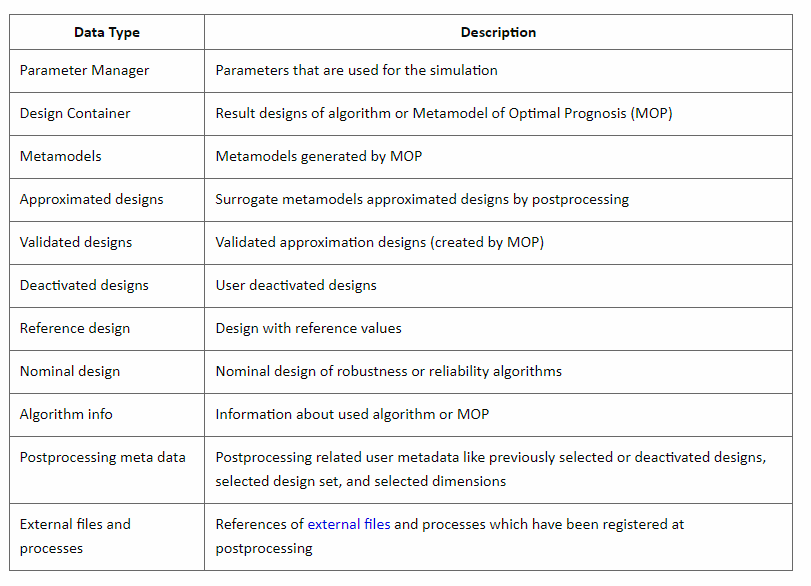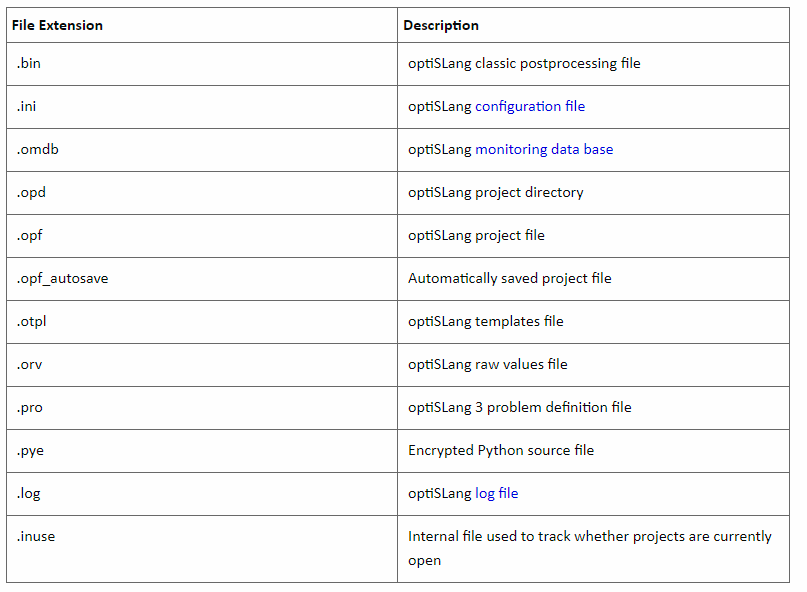

## 불러오기 

% OPDPath='D:\KangDH\Optislang_Motorcad\HDEV_Code4\OPD\'
OPDPath='G:\KangDH\optislangMotorcad\6p54s_delta'
% OPDPath='G:\KangDH\optislangMotorcad\6p54s_delta\6p54s_delta\optiSLangExport\ExportedProj.opd\Sensitivity'
% filename='Sensitivity1.csv'
filePath='6p54sDoE_export.csv'
Sensitivity1=readtable(fullfile(OPDPath,filePath))

이건 이 sensitivity에만 해당하는 코드(emf output을 잘못짬, 턴수 고려안하게 계산됨)


% Sensitivity1.o_LineEmfFund=Sensitivity1.o_LineEmfFund.*Sensitivity1.i_TurnLab/11


## 자동화 가능 (삭제 Variable 값만 입력받기)

Nan 데이터(행) 삭제 

Sensitivity1 = deleteRowsWithNaNs(Sensitivity1);

특정 문자열로 시작하는 field 이름 추출하기 

VariableNamesCSV=Sensitivity1.Properties.VariableNames;

% combinedCellVariable = vertcat(MotorCADSetVariableName, pythonSetVariableData);

matchingIndices = find(startsWith(VariableNamesCSV, 'const'));
deleteVariableNames=VariableNamesCSV(matchingIndices)

특정 문자열 field 삭제

% for i=1:length(deleteVariableNames)
%     Sensitivity1 = deleteFieldswithStr(Sensitivity1, deleteVariableNames{i});
% end
% 더 간단한 코드 
Sensitivity1 = removevars(Sensitivity1, deleteVariableNames);
%% 위에꺼 함수화
Sensitivity1=devPostOptislangCSV(Sensitivity1)

filename = 'PostSensitivity1.csv';
writetable(Sensitivity1, strcat(OPDPath,filename));

## Filter

thresholdData.VariableName='o_LineEmfFund'
thresholdData.threshold=1200;

,thresholdAboveData,thresholdBelowData

특정 field값이 threshold 이하면 행을 삭제

for i=1:length(thresholdData)
    VariableName=thresholdData(i).VariableName
    threshold=thresholdData(i).threshold
    Sensitivity1 = deleteRowsAboveThreshold(Sensitivity1, VariableName, threshold);
end
thresholdData.VariableName='o_Wh_Shaft'
thresholdData.threshold=9751.15462384000;


for i=1:length(thresholdData)
    VariableName=thresholdData(i).VariableName
    threshold=thresholdData(i).threshold
    Sensitivity1 = deleteRowsBelowThreshold(Sensitivity1, VariableName, threshold);
end


## ParetoPlot